%% TOPSIS
% 程序的预处理部分
clear;clc;
A=xlsread('CN社会稳定指标1980_2020.xlsx','B2:D42');%导入数据,注意范围
disp('请输入各列的指标类型(1.效益型（积极）,2.成本型（消极）,3.区间型,4.中间型)');

请输入各列的指标类型(1.效益型（积极）,2.成本型（消极）,3.区间型,4.中间型)


disp('输入数据为向量形式,要加[],比如：[1 2 1 2]')

输入数据为向量形式,要加[],比如：[1 2 1 2]


Type=input('Type=');
[n1,n2]=size(A);
year=1980:2020;
%% 决策矩阵正向化处理
% 将成本型、区间型和中间型指标转化为效益型指标
X=zeros(n1,n2);
for i=1:n2
    switch Type(i)
        case 1
            X(:,i)=A(:,i);
        case 2
            X(:,i)=G_Min2Max(A(:,i));
        case 3
            disp('请输入区间的上下界a,b:');
            a=input('a=');
            b=input('b=');
            X(:,i)=Inter2Max(A(:,i),a,b);
        case 4
            disp('请输入最好值value：');
            value=input('value=');
            X(:,i)=Mid2Max(A(:,i),value);
        otherwise
            disp('您输入的Type中的数据包含不属于1~4的数据，请修改！');       
    end
end
 
%% 正向矩阵规范法处理
% 为了将已正向化的矩阵消除量纲的影响，则需要对其进行规范化处理
sum_X=sqrt(sum(X.*X));
B=X./repmat(sum_X,n1,1);
 
%% 求加权规范矩阵
% 一个方案的各指标的重要程度不同，则需要对各指标赋予权值
% 构造权重向量主要方法有：层次分析法，熵权法和默认方法
weigh=ones(1,n2)./n2;%默认方法
C=B.* repmat(weigh,n1,1);
 
%% 计算与正负理想解的距离
C_up=max(C);% C_up(j)表示第j个指标的正理想解
C_down=min(C);
temp1=C-repmat(C_up,n1,1);%temp1为cij-C_up(j)的差值
temp2=C-repmat(C_down,n1,1);
D_up=sum(temp1.^2,2).^0.5;%D_up(i)即为第i个方案与正理想解的距离
D_down=sum(temp2.^2,2).^0.5;
result=D_down./(D_up+D_down);%计算各方案的综合指标
disp('result=');

result=


disp(result);  %打分

    0.2928
    0.3547
    0.4078
    0.4810
    0.5032
    0.4811
    0.4765
    0.4734
    0.4297
    0.3751
    0.4534
    0.4671
    0.4561
    0.3922
    0.3310
    0.3486
    0.3917
    0.4197
    0.4428
    0.4469
    0.4380
    0.3962
    0.3791
    0.3452
    0.3332
    0.3591
    0.3793
    0.3820
    0.3915
    0.4572
    0.4727
    0.5114
    0.5538
    0.5804
    0.5938
    0.6070
    0.6015
    0.6292
    0.6578
    0.6779
    0.6228



[sort_result,index]=sort(result,'descend');
disp('sort_result=');

sort_result=


disp(sort_result);

    0.6779
    0.6578
    0.6292
    0.6228
    0.6070
    0.6015
    0.5938
    0.5804
    0.5538
    0.5114
    0.5032
    0.4811
    0.4810
    0.4765
    0.4734
    0.4727
    0.4671
    0.4572
    0.4561
    0.4534
    0.4469
    0.4428
    0.4380
    0.4297
    0.4197
    0.4078
    0.3962
    0.3922
    0.3917
    0.3915
    0.3820
    0.3793
    0.3791
    0.3751
    0.3591
    0.3547
    0.3486
    0.3452
    0.3332
    0.3310
    0.2928



disp('index');

index


disp(index);

    40
    39
    38
    41
    36
    37
    35
    34
    33
    32
     5
     6
     4
     7
     8
    31
    12
    30
    13
    11
    20
    19
    21
     9
    18
     3
    22
    14
    17
    29
    28
    27
    23
    10
    26
     2
    16
    24
    25
    15
     1



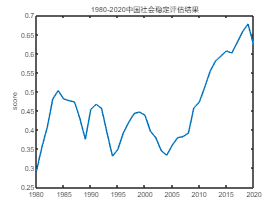

plot(year,result)%1980-2020社会稳定性分数曲线
title('1980-2020中国社会稳定评估结果')
ylabel('score')